## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from [OpenNeuro](https://docs.openneuro.org/user_guide.html) archive [1], pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The data was collected under the supervision of Arnaud Delorme, PhD ([Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu/)). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

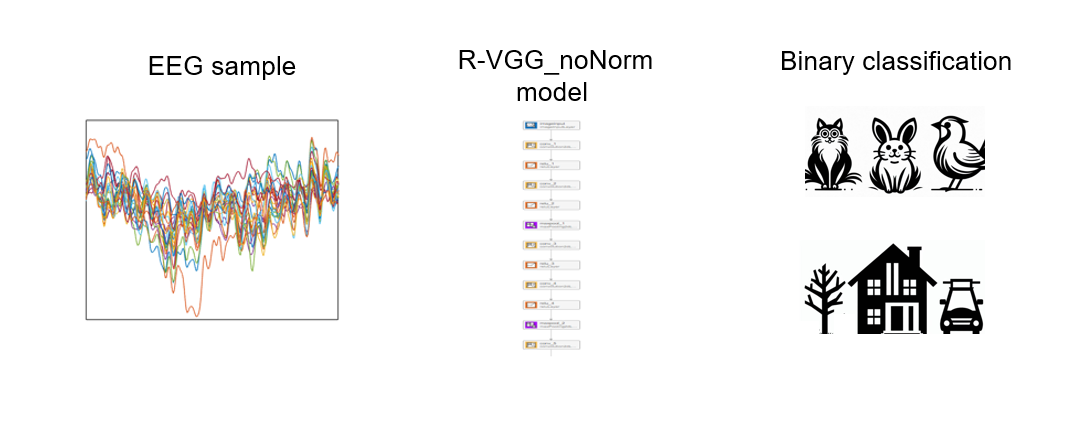

**Background on Dataset**

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 1024 Hz sampling rate. The data in OpenNeuro dataset was subsequently resampled at 1000 Hz. Individual samples consist of 0.5 sec signal across 31 channels, starting at the onset of individual visual stimuli.

**Background on Example**

In this example, we are demonstrating the binary (two classes) classification of visual stimuli based on the scalp EEG recordings.  The model was train to predict whether the visual stimulus presented during a given sample of brain activity contained an animal or not.

**BIDS Format**

BIDS format [3] defines the dataset structure and minimum information the dataset needs to contain. The EEG data files could be stored as one of the standard EEG formats (e.g. edf, EEGLAB, NWB). The EEG files in this dataset are stored in *.set format, produced by EEGLAB toolbox. The EEGLAB `pop_importbids` function downloads the BIDS dataset from the online repository and puts it in the EEGLAB format. 

curr_env = getenv; 

if isKey(curr_env,"MW_DDUX_APP_NAME")==1 & curr_env("MW_DDUX_APP_NAME")=='MATLAB_ONLINE'
    environment = 'online';
elseif isKey(curr_env,"MW_DDUX_APP_NAME")==0
    environment = 'local';
end

curr_dir = pwd;
if strcmp(environment, 'online')==1

    % FUTURE 
    % if isempty(which('eeglab'))
    %    matlab.addons.install(<MLTBX>)
    % end

    shallowRepoAddOrUpdate("https://github.com/sccn/eeglab","eeglab","eeglab"); 

    %addpath MATLAB Add-Ons/Collections/EEGLAB;%check if it's already in online repo
    %addpath '/MATLAB Drive/Repositories/study_ml';
else
    if exist('eeglab','dir')==1
        eeglab;%
    elseif exist('eeglab','dir')==7
        curr_dir = pwd;
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    else
        curr_dir = pwd;
        gitclone('https://github.com/sccn/eeglab');
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    end
end


shallowRepoAddOrUpdate("https://github.com/sccn/bids-matlab-tools","bids-matlab-tools","bids_loadfile"); 

% gitclone('https://github.com/sccn/bids-matlab-tools');
% addpath(sprintf('%s/bids-matlab-tools',curr_dir));
% addpath '/MATLAB Drive/Repositories/study_ml';
% 


base_dir = pwd;
dataset_ID = 'ds002680';

tic
helper.download_shrink_dataset(dataset_ID);

s3FilePath = "s3://openneuro.org/ds002680/"

Elapsed time is 84.763961 seconds.
Elapsed time is 135.768823 seconds.
Elapsed time is 135.930730 seconds.


toc

Elapsed time is 135.933689 seconds.


filePath = sprintf('%s/%s',base_dir,dataset_ID);
out_dir = sprintf('%s/DL',base_dir);
tic
[STUDY, ALLEEG] = eclipse.pop_importbids_integrated(filePath, environment, 'eventtype', 'value', 'outputdir', out_dir);

Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-13_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-13_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-13_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-13_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-13_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-13_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-10_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-10_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-11_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-11_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-12_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-12_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-1_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-1_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-2_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-2_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-3_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-3_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-4_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-4_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-5_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-5_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-6_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-6_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-7_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-7_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-8_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-8_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Importing file: /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-9_eeg.set
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/ds002680/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-9_eeg.set ...


Looking up/checking channel type from channel labels
eeg_checkset note: creating the original event table (EEG.urevent)
Event resorted by increasing latencies.
Saving dataset...
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-005 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-0005 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-00005 does not exist
No EEG data folder for subject sub-000005 session 
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-006 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-0006 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-00006 does not exist
No EEG data folder for subject sub-000006 session 
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-007 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-0007 does not exist
Folder /MATLAB Drive/eeglab_deep_learning/ds002680/sub-00007 does not exist
No EEG data folder for subject sub-000007 ses

Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-13_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-13_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-01/eeg/sub-002_ses-01_task-gonogo_run-9_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-10_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-002/ses-02/eeg/sub-002_ses-02_task-gonogo_run-9_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-10_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-13_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-13_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-01/eeg/sub-003_ses-01_task-gonogo_run-9_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-10_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-003/ses-02/eeg/sub-003_ses-02_task-gonogo_run-9_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-10_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-13_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-13_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-01/eeg/sub-004_ses-01_task-gonogo_run-9_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-10_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-10_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-11_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-11_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-12_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-12_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-1_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-1_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-2_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-2_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-3_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-3_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-4_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-4_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-5_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-5_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-6_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-6_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-7_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-7_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-8_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-8_eeg.fdt'...
pop_loadset(): loading file /MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-9_eeg.set ...


Reading float file '/MATLAB Drive/eeglab_deep_learning/DL/sub-004/ses-02/eeg/sub-004_ses-02_task-gonogo_run-9_eeg.fdt'...
Datasets are all continuous, so trial information is skipped.
Re-saving study file


toc

Elapsed time is 281.037342 seconds.


The pop_importbids function provides two outputs, **STUDY** (the EEGLAB structure defining the group analysis parameters) and **ALLEEG** (the structure containing all the loaded EEG datasets). 

**ALLEEG** is a structure with the first dimension equaling the number of loaded dataset.

- ALLEEG.**filename** - contains the filenames

- ALLEEG.**subject** - subject labels

- ALLEEG.**chanlocs** - channel labels and respective anatomical coordinates

- ALLEEG.**event** - information on trial timestamps and presented stimuli

- ALLEEG.**data** - EEG time series, organized as a matrix (n of channels x n of samples)

**Exploring the Dataset **

We can check the number of datasets and unique subjects.

helper.dataset_info(ALLEEG);

The example consists of 75 datasets, recorded from 3 unique subjects.
Individual datasets consist of 31 channels recorded at 1000 Hz. Recording durations are 202-227 sec.

## Preparing the data for DL training/inference format

`pop_studydl` EEGLAB function exports the EEG signals stored in EEGLAB structure into ML/DL data format. 

tic
if strcmp(environment,'local')==1
    [ALLEEG] = eclipse.pop_studydl_integrated(STUDY, ALLEEG, environment,'outputdir', fullfile(base_dir, 'ML_EXPORT'));
elseif strcmp(environment,'online')==1
    [ALLEEG, samples_all, sample_ID_all, labels_all] = eclipse.pop_studydl_integrated(STUDY, ALLEEG, environment, 'outputdir', fullfile(base_dir, 'ML_EXPORT'));
end

resampling data 128.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 
resampling event latencies...
Event resorted by increasing latencies.
resampling finished
Events file detected! Epochs will be generated with [0, 0.5] s time window 
pop_epoch():152 epochs selected
Epoching...
pop_epoch():152 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-10_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-11_eeg.set segments (n=153):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-12_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-13_eeg.set segments (n=156):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-1_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-2_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-3_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-4_eeg.set segments (n=154):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-5_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-6_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-7_eeg.set segments (n=149):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-8_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-01_task-gonogo_run-9_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-10_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-11_eeg.set segments (n=153):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-12_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-1_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-2_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-3_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-4_eeg.set segments (n=154):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-5_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-6_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-7_eeg.set segments (n=149):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-8_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_ses-02_task-gonogo_run-9_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-10_eeg.set segments (n=147):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-11_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-12_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-13_eeg.set segments (n=151):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-1_eeg.set segments (n=200):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-2_eeg.set segments (n=153):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-3_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-4_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-5_eeg.set segments (n=153):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-6_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-7_eeg.set segments (n=146):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-8_eeg.set segments (n=152):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-01_task-gonogo_run-9_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-10_eeg.set segments (n=147):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-11_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-12_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-1_eeg.set segments (n=200):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-2_eeg.set segments (n=153):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-3_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-4_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-5_eeg.set segments (n=153):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-6_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-7_eeg.set segments (n=146):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-8_eeg.set segments (n=152):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_ses-02_task-gonogo_run-9_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-10_eeg.set segments (n=151):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-11_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-12_eeg.set segments (n=150):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-13_eeg.set segments (n=154):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-1_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-2_eeg.set segments (n=149):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-3_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-4_eeg.set segments (n=147):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-5_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-6_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-7_eeg.set segments (n=148):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-8_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-01_task-gonogo_run-9_eeg.set segments (n=152):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-10_eeg.set segments (n=151):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-11_eeg.set segments (n=152):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-12_eeg.set segments (n=150):..............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-1_eeg.set segments (n=155):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-2_eeg.set segments (n=149):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-3_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-4_eeg.set segments (n=147):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-5_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-6_eeg.set segments (n=150):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-7_eeg.set segments (n=148):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-8_eeg.set segments (n=151):...............

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_ses-02_task-gonogo_run-9_eeg.set segments (n=152):...............

toc

Elapsed time is 94.146076 seconds.


### **Data visualization**

Next, we can plot the EEG trace from an example channel, e.g. the first channel from the first dataset.

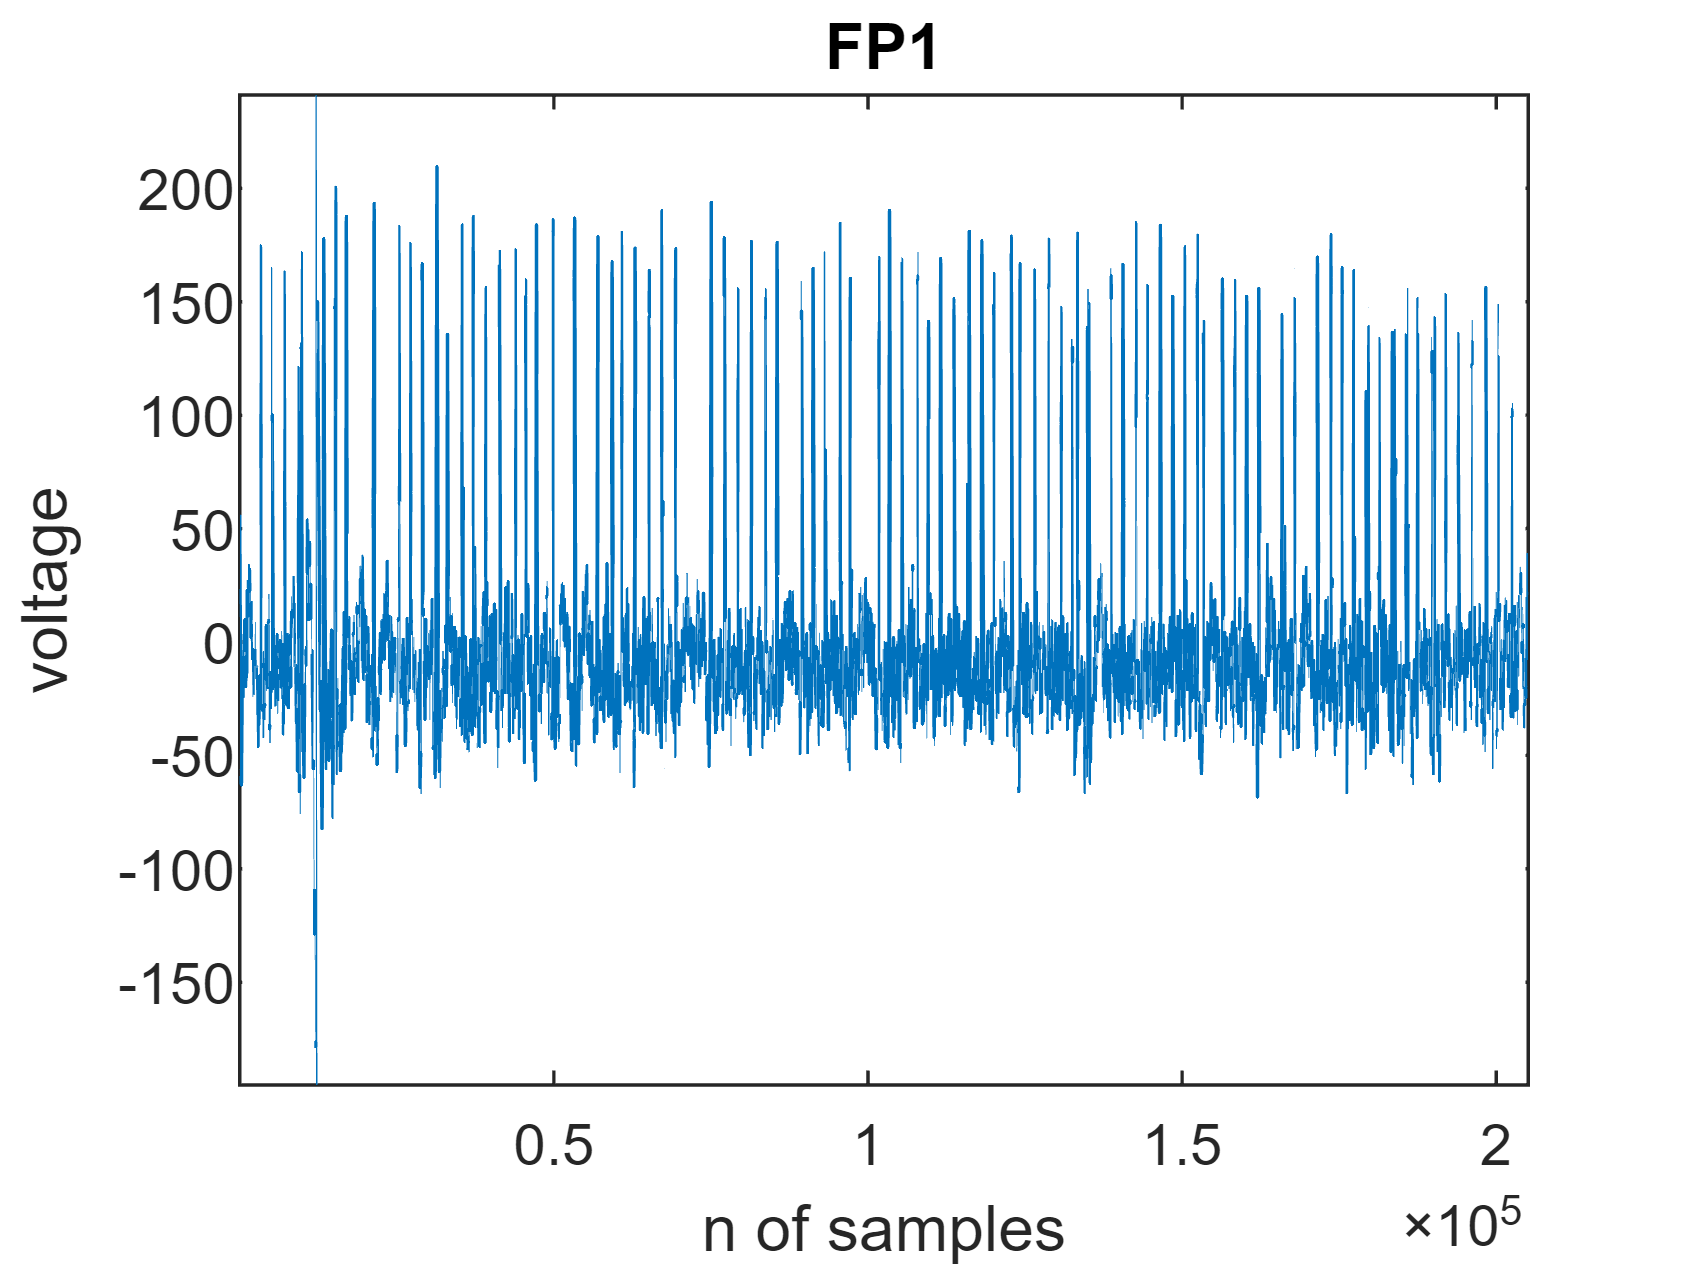

example_eeg_trace = ALLEEG(1).data(1,:);

figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

## Creating the datastore

selected_labels = {'animal_target','animal_distractor'}; 

if strcmp(environment,'local')==1
    [ds] = helper.create_datastore(base_dir, selected_labels, environment);
elseif strcmp(environment,'online')==1
    [ds, selected_sample_ID] = helper.create_datastore(base_dir, selected_labels, environment, labels_all, samples_all, sample_ID_all);
end


## Preview the first sample of the datastore

if strcmp(environment,'local')==1
    sample = preview(ds);
elseif strcmp(environment,'online')==1
    sample = preview(ds); sample = sample{1};
end

fprintf('Sample size = %d, %d, %d\n', size(sample));

Sample size = 31, 64, 

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on model performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are computed by the `compute_class_weights` helper function.

[classProportions, uniqueLabels] = helper.compute_class_proportions(ds,environment)

classProportions =     0.5000    0.5000


uniqueLabels = 1x2 cell array
    {'animal_distractor'}    {'animal_target'}


### Splitting the Datastore

Finally, we can split the datastore and evaluate the model performance. Splitting could be done so the training, testing and validation sets all contain the samples from all subjects or the different subjects. The choice can be indicated in the drop-down menu below.

splitting_mode = "subjects_mixed";

if strcmp(environment,'local')==1
[train_ds, val_ds, test_ds] = helper.split_datastore(ds, splitting_mode, environment, selected_labels, base_dir);
elseif strcmp(environment, 'online')==1
[train_ds, val_ds, test_ds] = helper.split_datastore(ds, splitting_mode, environment, selected_labels, base_dir, selected_sample_ID);
end


## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions and the output layer (`classificationLayer`) reflecting the number of class labels. A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the neural network **classification output layer**, provides the optional parameter classWeights to account for class weights in training process. 

if strcmp(environment,'local')==1
    classes = unique(train_ds.Labels);
    sample_size = size(preview(train_ds));
elseif strcmp(environment,'online')==1
    classes = categorical(selected_labels);
     sample = preview(train_ds); sample_size = size(sample{1});
end
    num_labels = numel(classes);

    
layers = [
    imageInputLayer(sample_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 


Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

maxEpochs = 10;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_ds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',maxEpochs, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);

eeg_net = trainNetwork(train_ds,layers,options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       60.00% |       47.78% |       0.7867 |       0.7410 |          0.0005 |
|       2 |          50 |       00:00:12 |       52.50% |       65.31% |       0.7034 |       0.6798 |          0.0005 |
|       3 |         100 |       00:00:18 |       55.00% |       69.01% |       0.6735 |       0.5881 |          0.0005 |
|       4 |         150 |       00:00:24 |       85.00% |       75.43% |       0.4539 |       0.4989 |          0.0005 |
|       

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

ds_all{1} = train_ds; ds_all{2} = val_ds; ds_all{3} = test_ds;

str_array = ["train" "val" "test"];

for i = 1:numel(str_array)
    curr_ds = ds_all{i};
    [YPred] = classify(eeg_net, curr_ds);
    if strcmp(environment,'local')==1
        curr_performance = sum(0+(curr_ds.Labels == YPred))/length(YPred);
    elseif strcmp(environment,'online')==1
        dataout = readall(curr_ds,UseParallel=true);
        labels_cell = dataout(:,2);
        for x  = 1:numel(labels_cell)
        if YPred(x) == categorical(labels_cell{x})
            curr_performance(x)=1;
        else
            curr_performance(x)=0;
        end
        end
    end
    performance_all(i) = mean(curr_performance);
    fprintf('Percent correct %s is %1.2f %%\n', str_array(i), mean(curr_performance)*100); clear curr_performance;
end

Percent correct train is 93.89 %
Percent correct val is 80.00 %
Percent correct test is 81.48 %


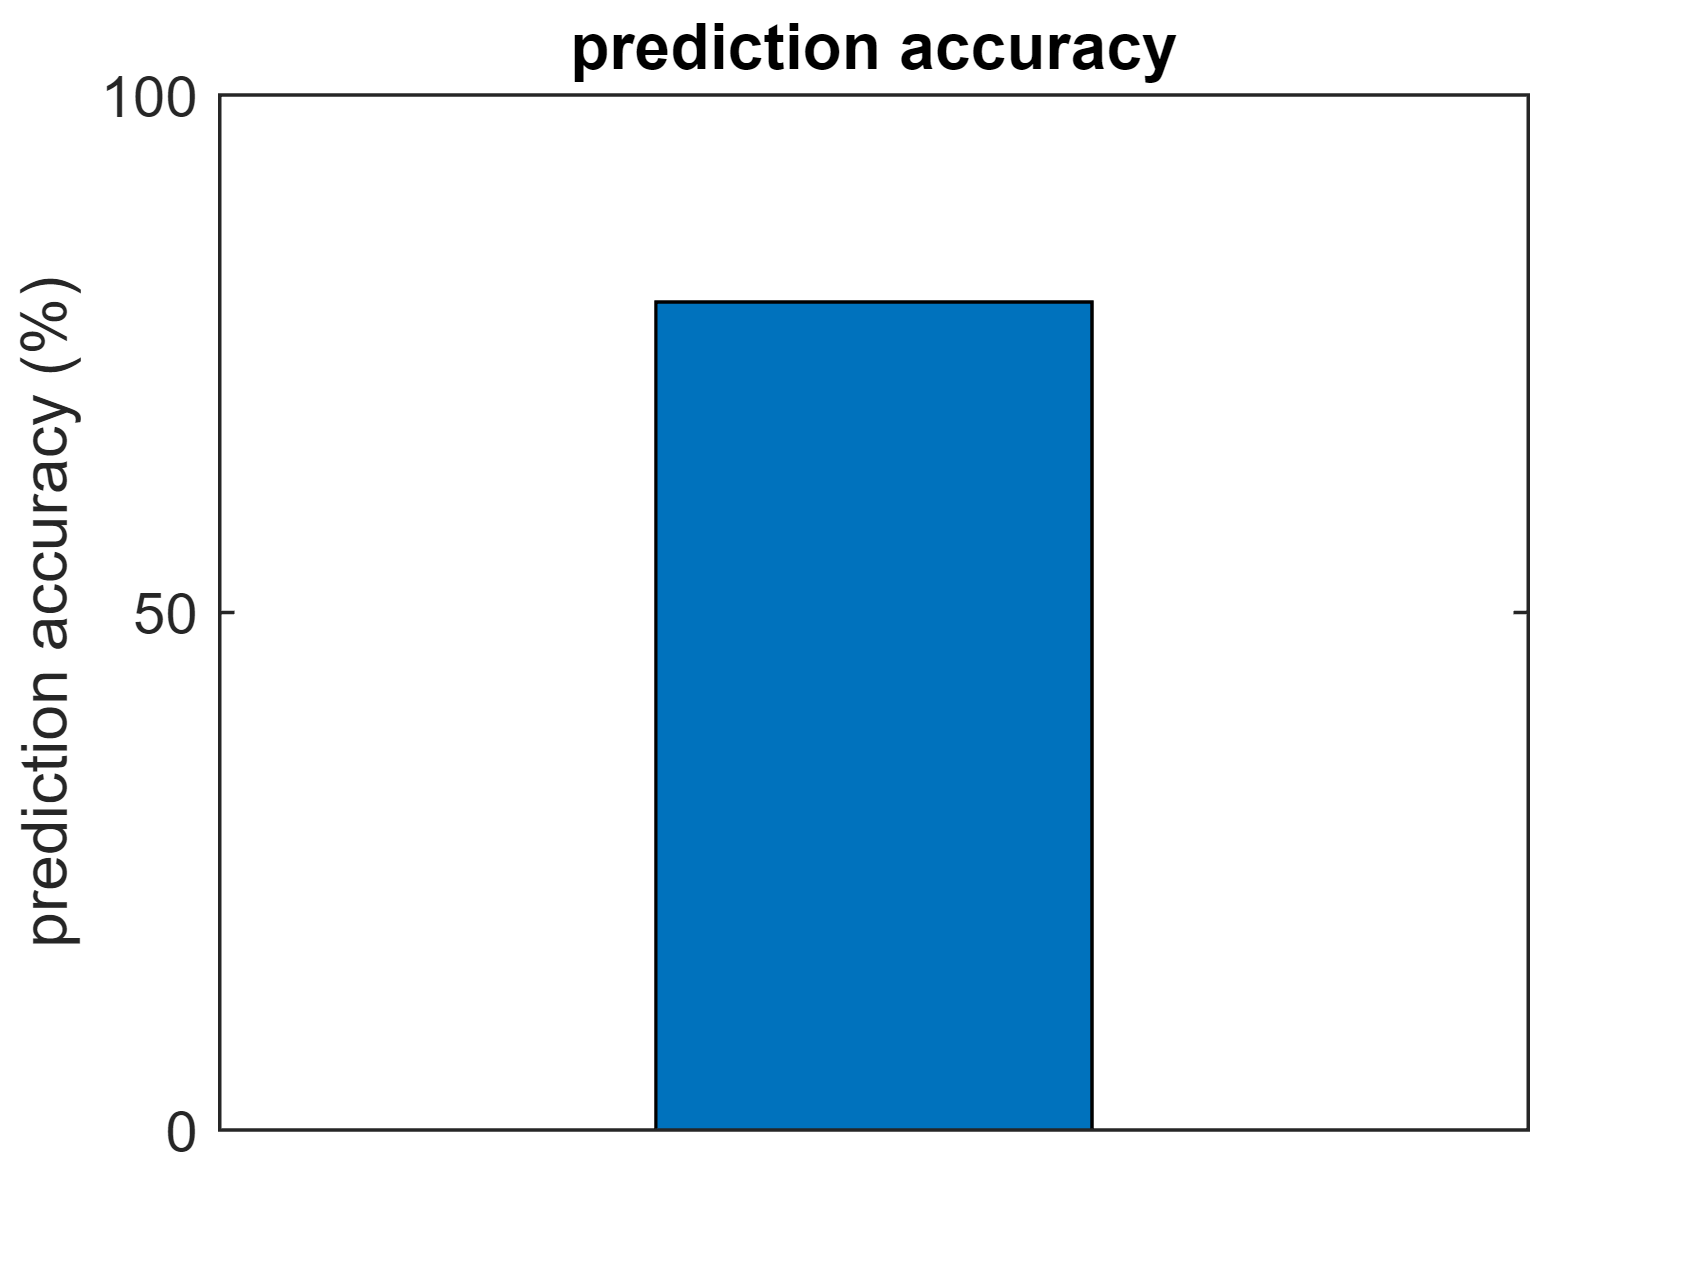

figure;bar(performance_all(2)*100);
title('prediction accuracy')
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])

**Contributors:**

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.

## Local Helpers

function shallowRepoAddOrUpdate(URL, folder, rootFolderFcn)

persistent hRepos

if isempty(hRepos)    
    hRepos = dictionary();
end


try 
    if hRepos.isConfigured && hRepos.isKey(URL)  % Case: previously installed during this MATLAB session
        assert(exist(folder,"dir"));
        assert(~isempty(which(rootFolderFcn)));
    else % Case: previously installed during a prior MATLAB session
        try 
            hRepo = matlab.git.GitRepository(folder);
        catch ME
            ME.rethrow(); %TODO: handle this failure case (previous but corrupted installation) separately 
        end

        hRepos(URL) = hRepo;
        
        % UPDATE
        hRepos(URL).fetch();
        tbl = hRepos(URL).log();
        if ~isequal(tbl.ID{1}, hRepos(URL).LastCommit.ID)
            hRepos(URL).pull();
        end  

        addpath(genpath(folder));
    end

catch
    % ADD   
    hRepos(URL) = gitclone(URL,folder,"Depth",1);
    addpath(genpath(folder));
end

end

